
alpha = 1 + mod(506 , 3);
t = 0:1/100:10; %100 samples in 10 sec
f1 = 2 + 2*(alpha);
f2 = 5 + 5*(alpha);

y = chirp(t, f1, 10, f2, 'linear')

y =     1.0000    0.8761    0.5346    0.0594   -0.4312   -0.8145   -0.9937   -0.9228   -0.6186   -0.1573    0.3446    0.7594    0.9807    0.9508    0.6764    0.2273   -0.2812   -0.7174   -0.9677   -0.9659   -0.7115   -0.2702    0.2428    0.6925    0.9595    0.9724    0.7266    0.2866   -0.2306   -0.6867   -0.9585   -0.9721   -0.7227   -0.2769    0.2448    0.7004    0.9650    0.9652    0.6998    0.2410   -0.2850   -0.7327   -0.9771   -0.9492   -0.6558   -0.1781    0.3503    0.7806    0.9907    0.9201


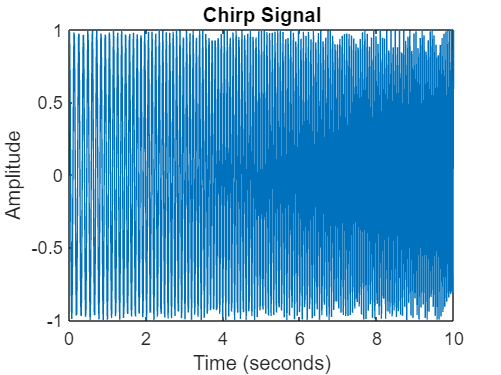



plot(t, y);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Chirp Signal');

Fs = 100;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 10;             % Length of signal
t = (0:L-1)*T;        % Time vector


Fs1 = 1000;  
t = 0:1/Fs1:(99/Fs1); 


y2 = fft(y);
mag = abs(y2);


N = length(y2)

N = 1001

freq1 = (0:N-1) * (Fs1 / N)

freq1 =          0    0.9990    1.9980    2.9970    3.9960    4.9950    5.9940    6.9930    7.9920    8.9910    9.9900   10.9890   11.9880   12.9870   13.9860   14.9850   15.9840   16.9830   17.9820   18.9810   19.9800   20.9790   21.9780   22.9770   23.9760   24.9750   25.9740   26.9730   27.9720   28.9710   29.9700   30.9690   31.9680   32.9670   33.9660   34.9650   35.9640   36.9630   37.9620   38.9610   39.9600   40.9590   41.9580   42.9570   43.9560   44.9550   45.9540   46.9530   47.9520   48.9510


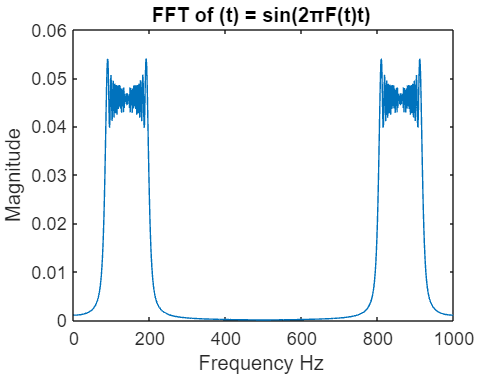


plot(freq1 , mag/N)
title('FFT of (t) = sin(2πF(t)t) ')
xlabel('Frequency Hz ')
ylabel('Magnitude')

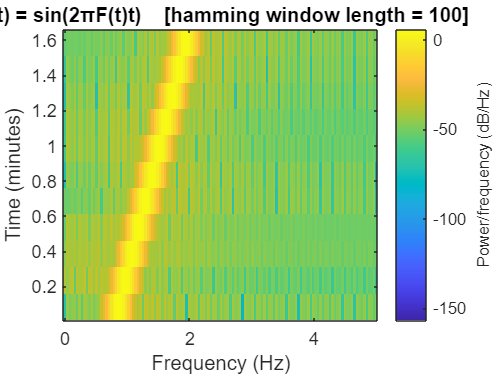

alpha = 1 + mod(506 , 3);
t = 0:1/100:10; %100 samples in 10 sec
f1 = 2 + 2*(alpha);
f2 = 5 + 5*(alpha);

 x1 = sin(2*pi*f1*t); 
 x2 = sin(2*pi*f2*t);
y3 = chirp(t, f1, 10, f2, 'linear');
x = sin(2 * pi * chirp(t, f1, 10, f2, 'linear'));
%is not required since chirp contains cosine in it


spectrogram(y3,hamming(100),10,[],10);
title(' x(t) = sin(2πF(t)t)    [hamming window length = 100]');

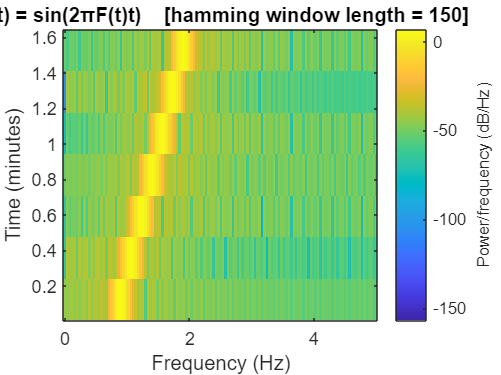

spectrogram(y3,hamming(150),10,[],10);
title(' x(t) = sin(2πF(t)t)    [hamming window length = 150]');

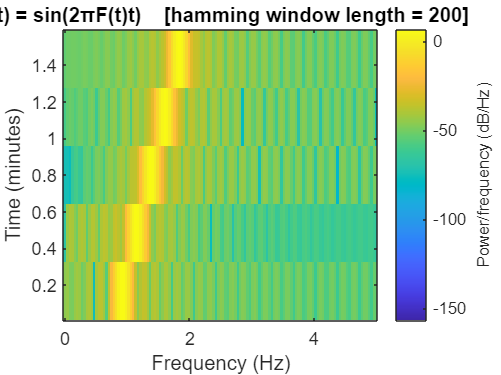

spectrogram(y3,hamming(200),10,[],10);


title(' x(t) = sin(2πF(t)t)    [hamming window length = 200]');

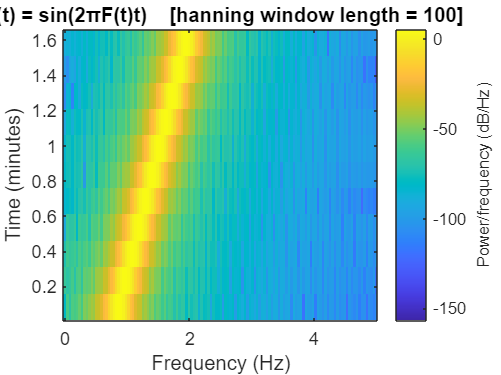

alpha = 1 + mod(506 , 3);
t = 0:1/100:10; %100 samples in 10 sec
f1 = 2 + 2*(alpha);
f2 = 5 + 5*(alpha);

 x1 = sin(2*pi*f1*t); 
 x2 = sin(2*pi*f2*t);
y3 = chirp(t, f1, 10, f2, 'linear');
x = sin(2 * pi * chirp(t, f1, 10, f2, 'linear'));
%is not required since chirp contains cosine in it


spectrogram(y3,hanning(100),10,[],10);
title(' x(t) = sin(2πF(t)t)    [hanning window length = 100]');

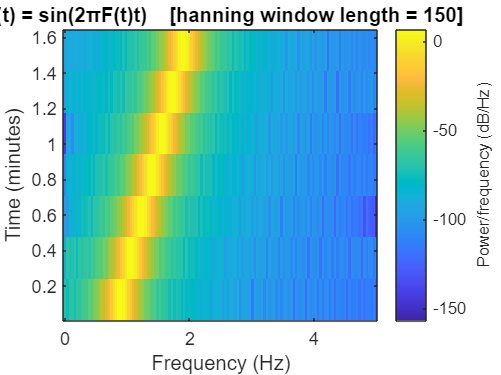

spectrogram(y3,hanning(150),10,[],10);
title(' x(t) = sin(2πF(t)t)    [hanning window length = 150]');

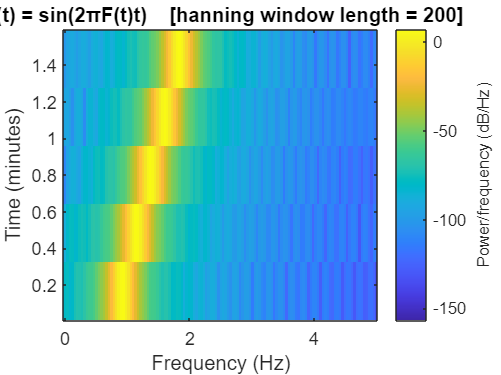

spectrogram(y3,hanning(200),10,[],10);


title(' x(t) = sin(2πF(t)t)    [hanning window length = 200]');

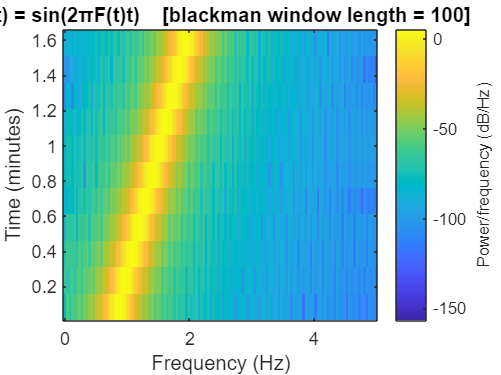

alpha = 1 + mod(506 , 3);
t = 0:1/100:10; %100 samples in 10 sec
f1 = 2 + 2*(alpha);
f2 = 5 + 5*(alpha);

 x1 = sin(2*pi*f1*t); 
 x2 = sin(2*pi*f2*t);
y3 = chirp(t, f1, 10, f2, 'linear');
x = sin(2 * pi * chirp(t, f1, 10, f2, 'linear'));
%is not required since chirp contains cosine in it


spectrogram(y3,hanning(100),10,[],10);
title(' x(t) = sin(2πF(t)t)    [blackman window length = 100]');

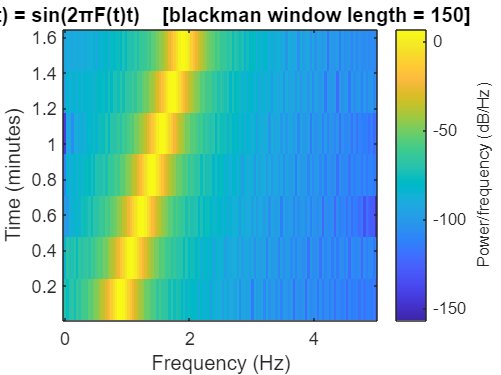

spectrogram(y3,hanning(150),10,[],10);
title(' x(t) = sin(2πF(t)t)    [blackman window length = 150]');

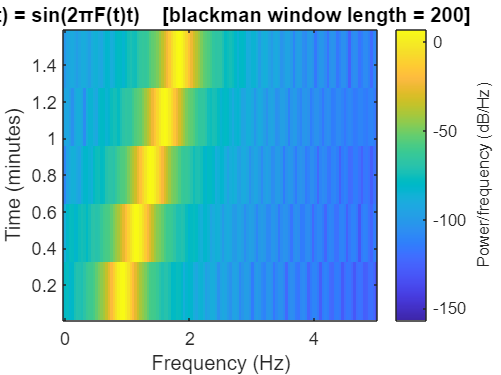

spectrogram(y3,hanning(200),10,[],10);


title(' x(t) = sin(2πF(t)t)    [blackman window length = 200]');

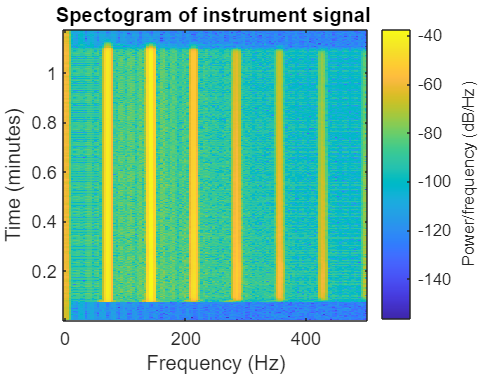

b = audioread('instru3.wav');
spectrogram(b,hamming(200),40,[],1000);
title('Spectogram of instrument signal ');

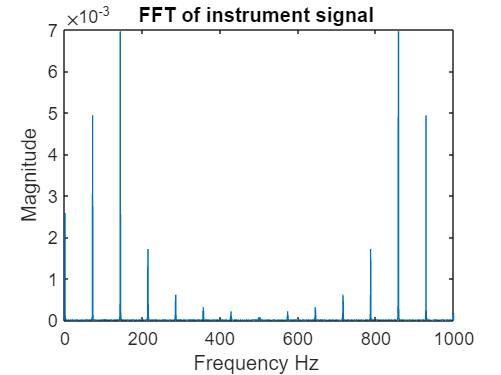


Fs1 = 1000;  
t = 0:1/Fs1:(99/Fs1); 


b2 = fft(b);
mag = abs(b2);


N = length(b2);
freq1 = (0:N-1) * (Fs1 / N);

plot(freq1 , mag/N)
title('FFT of instrument signal ')
xlabel('Frequency Hz ')
ylabel('Magnitude')

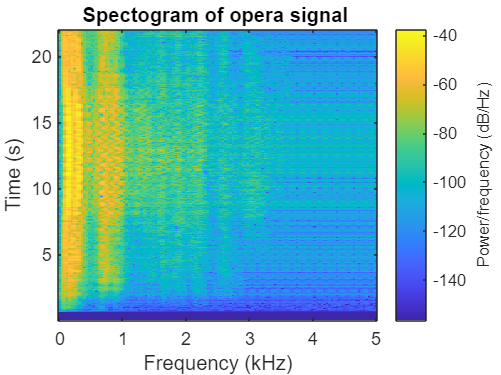

b1 = audioread('opera.wav');
spectrogram(b,hamming(200),40,[],10000);
title('Spectogram of opera signal ')

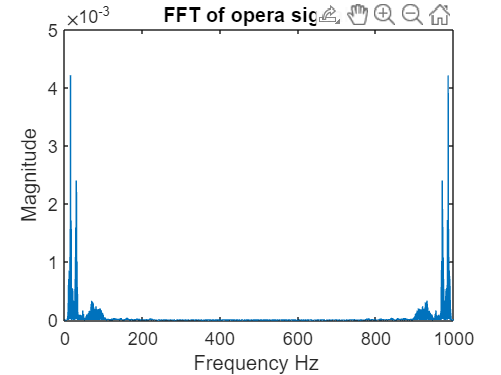


Fs1 = 1000;  
t = 0:1/Fs1:(99/Fs1); 


b3 = fft(b1);
mag5 = abs(b3);


N = length(b3);
freq1 = (0:N-1) * (Fs1 / N);

plot(freq1 , mag5/N)
title('FFT of opera signal ')
xlabel('Frequency Hz ')
ylabel('Magnitude')

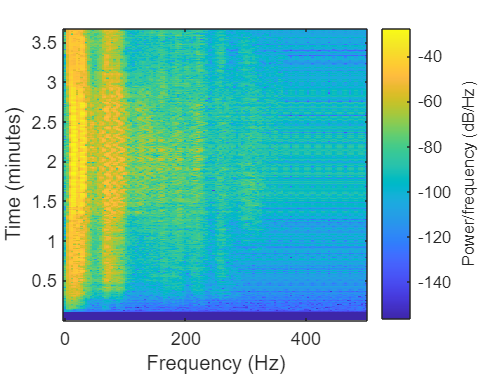

% Load the .wav file using audioread
filename = 'Name1.mp4';
[audio, sampleRate] = audioread('arpitha_audio.opus');
[S, F, T] = spectrogram(audio,hamming(22000), 11000,512,Fs);
figure;
imagesc(T, F, 20*log10(abs(S))); % Convert to dB for better visualization
axis xy; % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Name(Shreelakshmi)');
colorbar ;
colormap('jet'); % You can choose a different colormap if desired